Chargement du fichier du prof :

load('C:\Users\Utilisateur\telecom\2A\S4\auto\TD1\EssaiIndicielTemp.mat');

s = tf('s');
X = 0.5 * (1 / s);
t = (-5 * Te):Te:(60 * Te);
T = 2;

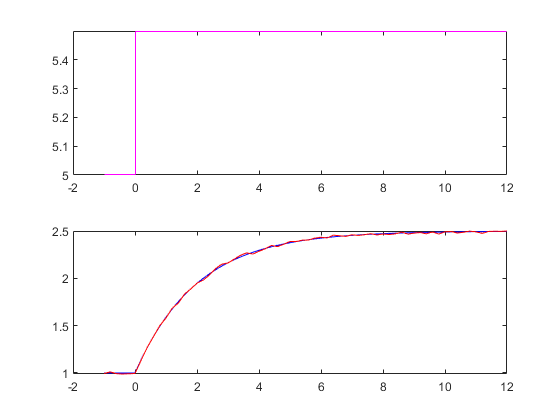

K1 = 3;
H1 = K1 / (1 + s * T);
a = impulse(H1 * X, t) + 1;
y1 = [ones([5 1]); a];
figure();
subplot(2, 1, 1);
stairs(t, temp, "-m");
subplot(2, 1, 2);
plot(t, y1, "-b", t, y, "-r");


$$Y(s) = K \cdot ( X(s) - Y(s) ) \cdot \frac{1}{1 + s \cdot T}$$



$$Y(s) \cdot \left(1 + \frac{K}{1 + s \cdot T} \right) = \frac{K}{1 + s \cdot T} \cdot X(s)$$



$$H(s) = \frac{Y(s)}{X(s)} = \frac{K}{1 + K + s \cdot T} = \frac{\frac{K}{1 + K}}{1 + s \cdot \frac{T}{1 + K}}$$


Donc $G(0) = \frac{K}{1 + K}$ et $\tau = \frac{T}{1 + K}$

K2 = 3;
H2 = (K2 / (1 + K2)) / (1 + s * (T / (1 + K2)));
y2 = impulse(H2 * X, t);
% figure();
% plot(t, y2, "-b");